# 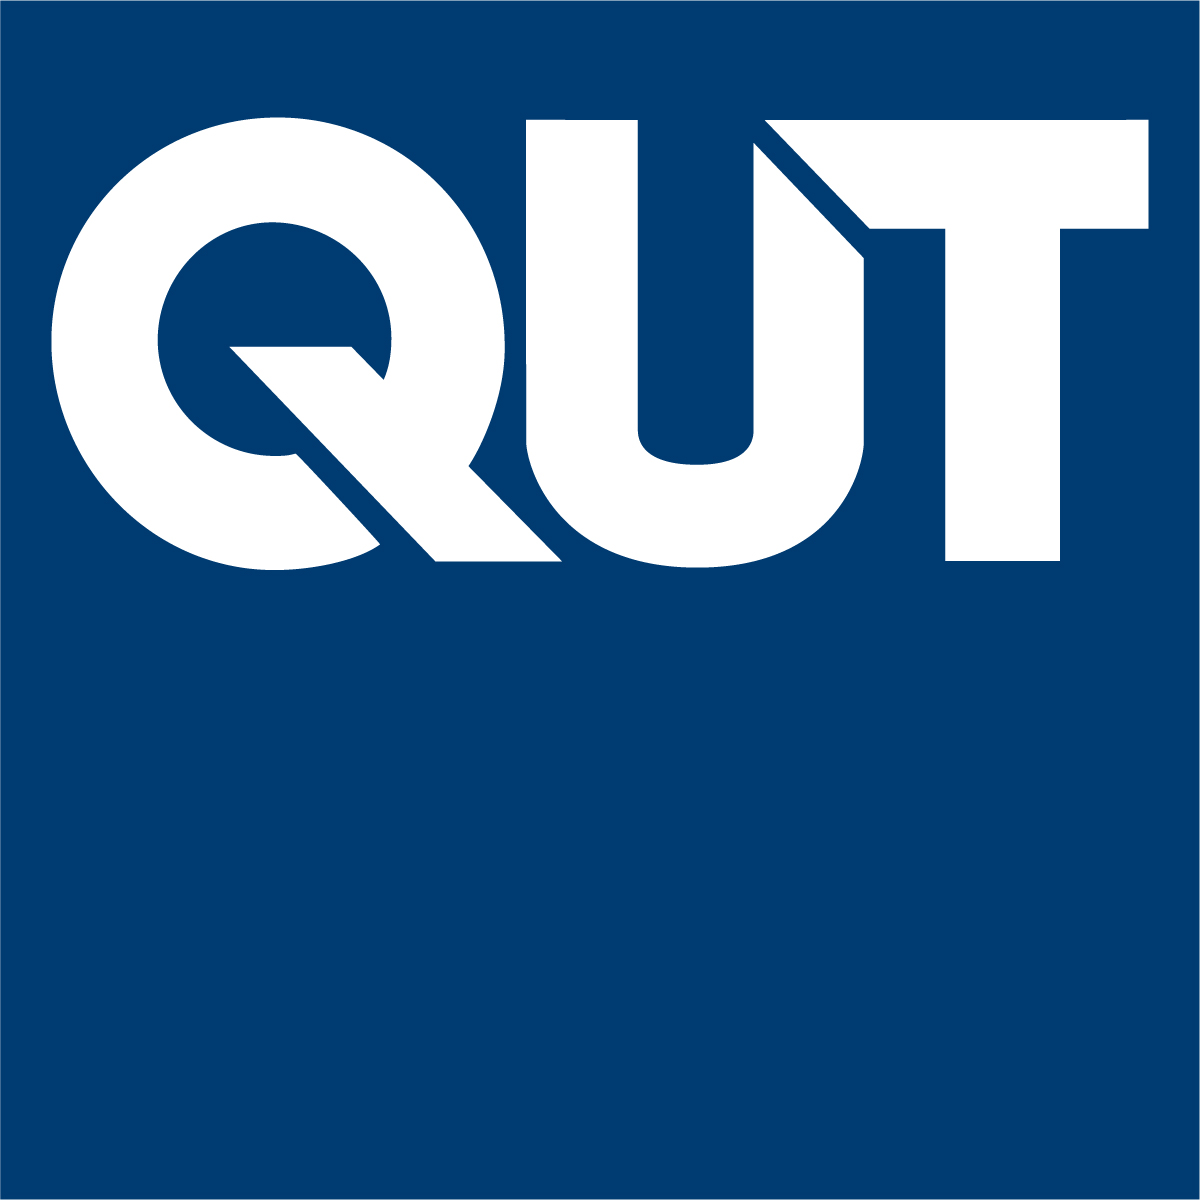

# MXB201 Chapter 5: Singular Value Decomposition

Professor Tim Moroney,  2022

V1.0

## 5.1 Introduction

[Video](https://web.microsoftstream.com/video/1a084038-077c-485d-be68-d0ed99687fb7)

We learned in Chapter 4 that symmetric matrices have an orthogonal diagonalisation $A = QDQ^T$.  Let's take a $2 \times 2$ example to remind ourselves how it works.

A = sym([3/2 -1 ; -1 3/2])

$$A = \left(\begin{array}{cc} \frac{3}{2} & -1\\ -1 & \frac{3}{2} \end{array}\right)$$

We leave it to the reader to derive the orthogonal diagonalisation:

D = sym(diag([5/2, 1/2]))

$$D = \left(\begin{array}{cc} \frac{5}{2} & 0\\ 0 & \frac{1}{2} \end{array}\right)$$

Q = sym([-1 1 ; 1 1] / sqrt(2))

$$Q = \left(\begin{array}{cc} -\frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} \end{array}\right)$$

isequal(A, Q*D*Q')

ans = logical
   1


Think about what this implies for our little matrix animation program.

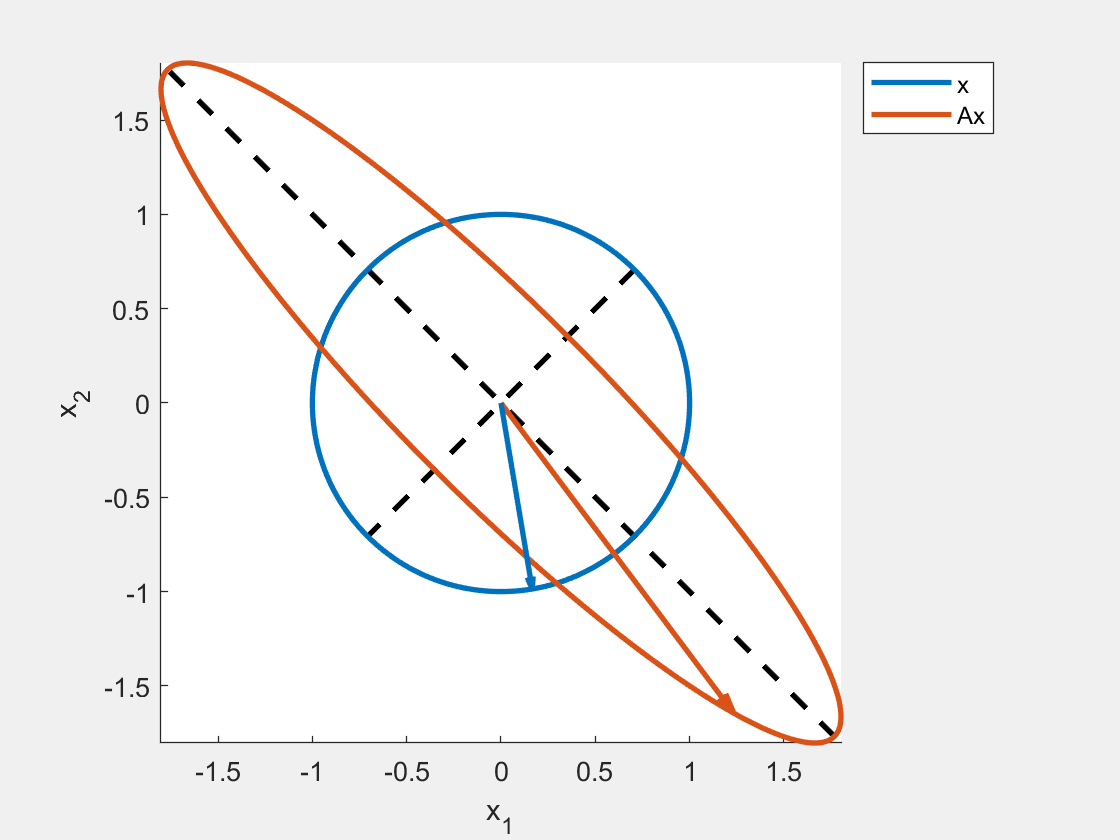

animate_matrix(A, 'e')  % animation #1

Remember, to make this animation, we are taking $x$ to be a unit vector (blue), and finding the product $Ax$ (red).  For this symmetric matrix, we know that $Ax = QDQ^Tx$ where $Q$ is an orthogonal matrix.  We can therefore think of the product $Ax$ as the result of applying three transformations: $Q(D(Q^Tx))$.  In words:

- Multiply $x$ by $Q^T$.

- Multiply the output from step 1 by $D = \textrm{diag}(\lambda_1, \lambda_2)$.

- Multiply the output from step 2 by $Q$.

Now, multiplication by an orthogonal matrix does not change the length of a vector: orthogonal matrices correspond only to rotations and/or reflections.  Hence, steps 1 and 3 are not responsible for the observed stretching/squishing of the unit circle into an ellipse.  It is only step 2, multiplication by the diagonal matrix $D$ that can be responsible for this.

Putting it another way, $x$ ranges over the unit circle, and $Q^Tx$ preserves this circle (since $Q$ represents a rotation or reflection -- which leaves a circle unchanged).  Then, multiplication by $D$ stretches the circle out by $\lambda_j$ along each coordinate axis, producing an ellipse.  Finally, multiplication by $Q$ rotates or reflects the ellipse into its final position.

Hence the lengths of the principal semi-axes of the ellipse are the eigenvalues $\lambda_j$, and their directions are $q_j$.

For our example, the larger eigenvalue is $\lambda_1 = 2.5$, which gives the length of the semi-major axis.  The corresponding eigenvector $q_1$ gives the direction of that axis.  Here it is as a still image:

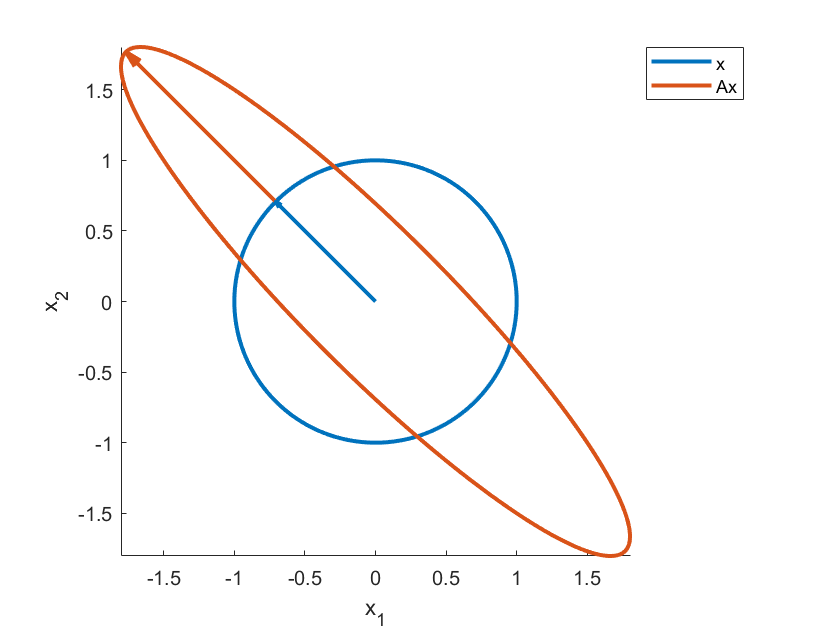

animate_matrix(A, [], Q(:,1)) 

Similarly, the semi-minor axis of the ellipse aligns with the eigenvector $q_2$, and its length is given by the smaller eigenvalue $\lambda_2 = 0.5$.

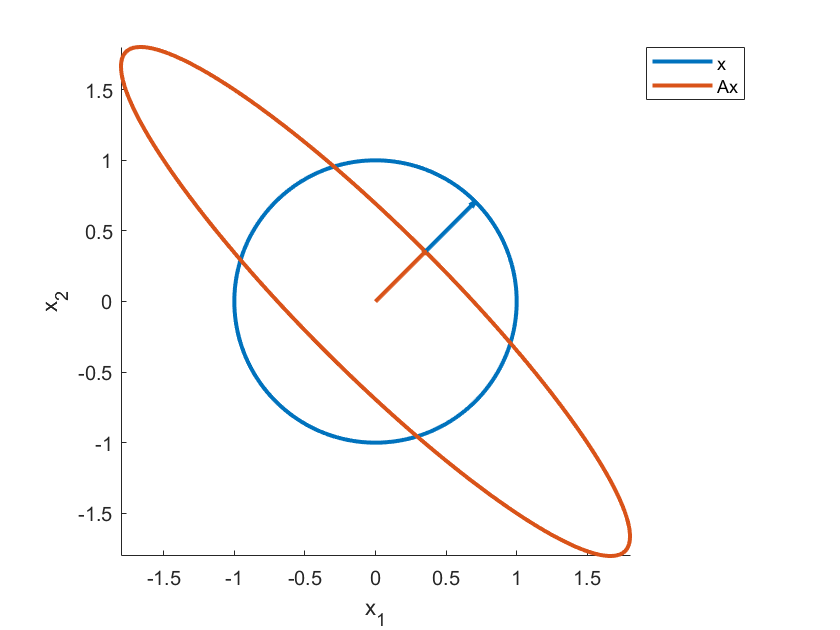

animate_matrix(A, [], Q(:,2))

Notice how it was essential to this argument that $A$ had an *orthogonal* diagonalisation $A = QDQ^T$.  Indeed, we already saw in Chapter 4, the conclusions we drew above are generally *not true* for arbitrary (nonsymmetric) $A$.  Our first example in Chapter 4, Section 4.2 was nonsymmetric:

A = sym([1 -1/5 ; -4/5 1])

$$A = \left(\begin{array}{cc} 1 & -\frac{1}{5}\\ -\frac{4}{5} & 1 \end{array}\right)$$

If you experiment with pausing the animation, you might discover that the unit vector $x$ that $A$ maps to the semi-major axis is around $[-0.8, 0.6]^T$:

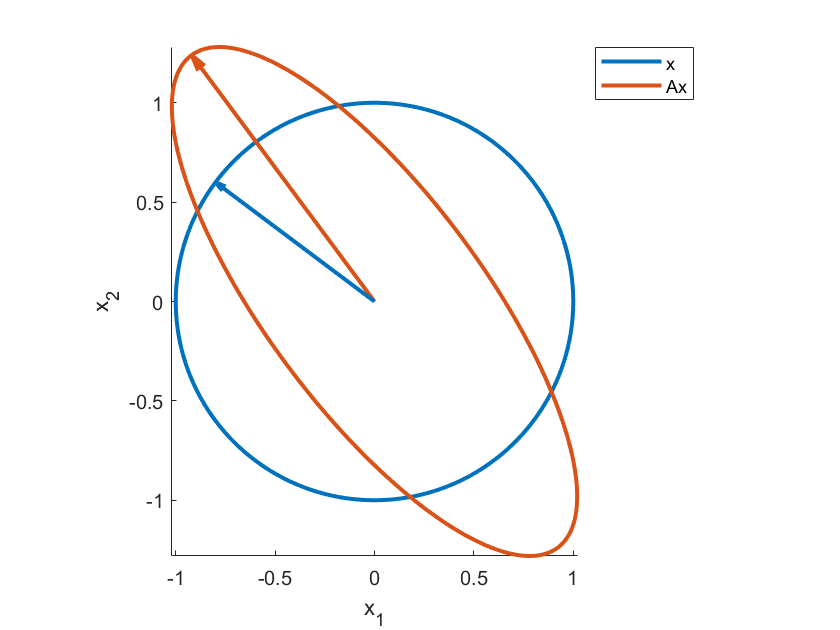

animate_matrix(A, [], [-0.8, 0.6])

As is obvious from the figure, this certainly isn't an eigenvector of $A$!

And anyway, not all matrices even *have* real eigenvalues.  For example, in Section 4.5 of Chapter 4 we looked at this example

A = sym([3/2 -1 ; 2 -1/2])

$$A = \left(\begin{array}{cc} \frac{3}{2} & -1\\ 2 & -\frac{1}{2} \end{array}\right)$$

which has complex eigenvalues,

eig(A)

$$ans = \left(\begin{array}{c} \frac{1}{2}-\mathrm{i}\\ \frac{1}{2}+\mathrm{i} \end{array}\right)$$

but its animation still produced a (very real!) ellipse.  Again, you might pause the animation and find that the preimage of the semi-major axis is around $x \approx [-0.92, 0.38]^T$.

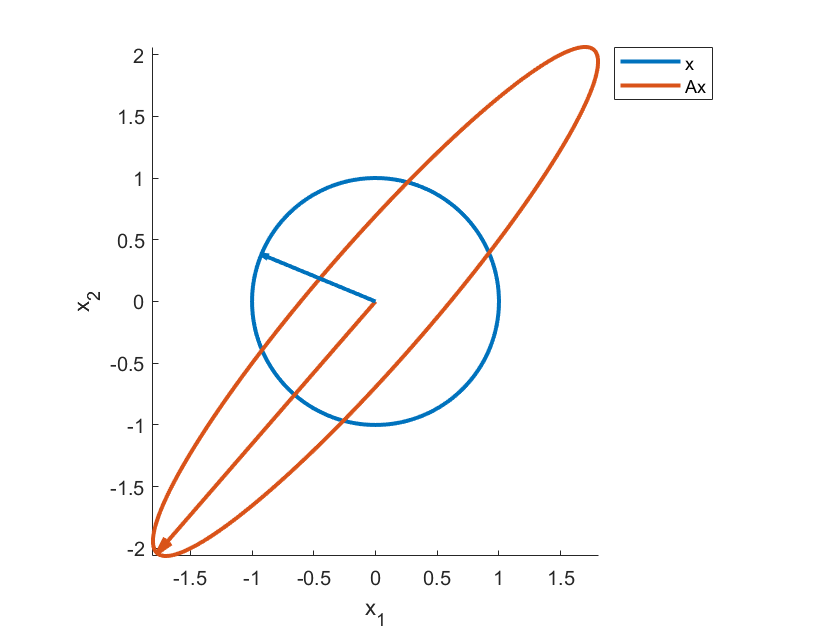

animate_matrix(A, [], [-0.92,0.38])

Clearly eigenvalues aren't the right way to understand what's going on here.

What we need, for the argument we made about symmetric matrices to generalise, is some *new kind of matrix decomposition* with the same flavour as $A = QDQ^T$, but which applies more generally.  From the image above, we see clearly that $x$ (blue) and $Ax$ (red) certainly *do not align* at the semi-major and semi-minor axes in general.  This is inconsistent with the relation $AQ = QD$ implied by the eigenvalue-based diagonalisation.  So we might be motivated to loosen the requirement to simply$AV = UD$, where $U$ and $V$ are *two different orthogonal matrices.*  In fact, let's not re-use the symbol $D$, we'll save that for eigenvalue diagonalisation.  We'll instead use $\Sigma$, and look for a matrix decomposition $A V = U \Sigma$, where $\Sigma$ is diagonal, and $U$ and $V$ are both orthogonal.  This decomposition, which does indeed exist, is known as the **singular value decomposition**, or **SVD.**

*The singular value decomposition (SVD) of *$A$* is given by *$A = U \Sigma V^T$*.*

## 5.2 Deriving the SVD

[Video](https://web.microsoftstream.com/video/8f01907b-d0f9-4e27-941f-42a1d194a4cb)

Well, we've jumped the gun a little bit there.  Are we sure that such a decomposition exists?  Let's play around a little with our desired equation $A = U \Sigma V^T$ to try to convince ourselves that it does.  We're still assuming (for now!) that $A$ is square.  Since we had luck previously with symmetric matrices, a moment of inspiration might lead us to wonder what the decomposition $A = U \Sigma V^T$ would imply for the *symmetric* matrices $A^TA$ and $AA^T$.  Well, if $A = U\Sigma V^T$ holds, then


$$A^TA = (U\Sigma V^T)^T (U\Sigma V^T) = V \Sigma^T U^T U \Sigma V^T = V \Sigma^2 V^T$$


and

$AA^T = (U\Sigma V^T)(U\Sigma V^T)^T = U \Sigma V^T V \Sigma^T U^T = U \Sigma^2 U^T$.

So the columns of the orthogonal matrix $V$ would need to be eigenvectors of $A^TA$, and the columns of the orthogonal matrix $U$ would need to be eigenvectors of $AA^T$.  The eigenvalues of *both* $A^TA$ and $AA^T$ would need to be $\Sigma^2$.  Is all this possible?  Yes!

We know from Chapter 4 that symmetric matrices have orthogonal diagonalisations, so finding suitable matrices $V$ and $U$ is certainly possible.  As for $\Sigma$, we know that (for square $A$) $A^TA$ and $AA^T$ have the same eigenvalues (Exercises 4, T3).  Furthermore, both $A^TA$ and $AA^T$ are positive semi-definite, meaning their eigenvalues are non-negative, so there is no problem with writing their common eigenvalue matrix as $\Sigma^2$.  We're all good!

Although we derived the SVD from the perspective of diagonalising $A^TA$ and $AA^T$, it is fiddly and inefficient to actually perform the computations this way.  Just to give you an idea of why, we will actually compute the SVD of our most recent example this way.

A

$$A = \left(\begin{array}{cc} \frac{3}{2} & -1\\ -1 & \frac{3}{2} \end{array}\right)$$

To do so, we will orthogonally diagonalise both $A^TA$ and $AA^T$.

Here are suitable diagonalisations $A^TA = VDV^T$ and $AA^T = UDU^T$ that you can verify for yourself.  They're not pretty when written out in symbolic form, that's for sure.  SVDs are basically never done in symbolic arithmetic, but we'll persist just this once, if only to get that sweet `isequal` payoff at the end.

U = [((sym(5)*sqrt(2))/7 - sym(1/7))/sqrt(((sym(5)*sqrt(2))/7 - sym(1/7))^sym(2) + 1), -((sym(5)*sqrt(2))/7 + sym(1/7))/sqrt(((sym(5)*sqrt(2))/7 + sym(1/7))^sym(2) + 1); 1/sqrt(((sym(5)*sqrt(2))/7 - sym(1/7))^sym(2) + 1), 1/sqrt(((sym(5)*sqrt(2))/7 + sym(1/7))^sym(2) + 1)]

$$U = \left(\begin{array}{cc} \frac{\frac{5\,\sqrt{2}}{7}-\frac{1}{7}}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}-\frac{1}{7}\right)}^{2}+1}} & -\frac{\frac{5\,\sqrt{2}}{7}+\frac{1}{7}}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}+\frac{1}{7}\right)}^{2}+1}}\\ \frac{1}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}-\frac{1}{7}\right)}^{2}+1}} & \frac{1}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}+\frac{1}{7}\right)}^{2}+1}} \end{array}\right)$$

V = [(sqrt(sym(2)) + 1)/sqrt((sqrt(sym(2)) + 1)^sym(2) + 1), (sqrt(sym(2)) - 1)/sqrt((sqrt(sym(2)) - 1)^sym(2) + 1); -1/sqrt((sqrt(sym(2)) + 1)^sym(2) + 1), 1/sqrt((sqrt(sym(2)) - 1)^sym(2) + 1)]

$$V = \left(\begin{array}{cc} \frac{\sqrt{2}+1}{\sqrt{{\left(\sqrt{2}+1\right)}^{2}+1}} & \frac{\sqrt{2}-1}{\sqrt{{\left(\sqrt{2}-1\right)}^{2}+1}}\\ -\frac{1}{\sqrt{{\left(\sqrt{2}+1\right)}^{2}+1}} & \frac{1}{\sqrt{{\left(\sqrt{2}-1\right)}^{2}+1}} \end{array}\right)$$

D = diag([10*sqrt(sym(2)) + 15, 15 - 10*sqrt(sym(2))]/4)

$$D = \left(\begin{array}{cc} \frac{5\,\sqrt{2}}{2}+\frac{15}{4} & 0\\ 0 & \frac{15}{4}-\frac{5\,\sqrt{2}}{2} \end{array}\right)$$

First, confirm these are indeed orthogonal diagonalisations of $A^TA$ and $AA^T$.

isequal(A'*A, simplify(V*D*V'))   % A'*A = V*D*V'

ans = logical
   1

isequal(A*A', simplify(U*D*U'))  % A*A' = U*D*U'

ans = logical
   1

simplify(V'*V), simplify(U'*U)  % V and U are orthogonal

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

So we have all that we need for our SVD.  The matrices $V$ and $U$ are ready.  And $\Sigma$ will be made up of the *square roots* of $D$ (square roots, so that $A^TA = V\Sigma^2V^T$ and $AA^T = U\Sigma^2U^T$ as required).

Sigma = sqrt(D)  % element-wise square root does the trick

$$Sigma = \left(\begin{array}{cc} \sqrt{\frac{5\,\sqrt{2}}{2}+\frac{15}{4}} & 0\\ 0 & \sqrt{\frac{15}{4}-\frac{5\,\sqrt{2}}{2}} \end{array}\right)$$

Voila!  Our SVD is given by $A = U\Sigma V^T$ where $U$, $V$ and $\Sigma$ are given by:

U, V, Sigma

$$U = \left(\begin{array}{cc} \frac{\frac{5\,\sqrt{2}}{7}-\frac{1}{7}}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}-\frac{1}{7}\right)}^{2}+1}} & -\frac{\frac{5\,\sqrt{2}}{7}+\frac{1}{7}}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}+\frac{1}{7}\right)}^{2}+1}}\\ \frac{1}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}-\frac{1}{7}\right)}^{2}+1}} & \frac{1}{\sqrt{{\left(\frac{5\,\sqrt{2}}{7}+\frac{1}{7}\right)}^{2}+1}} \end{array}\right)$$

$$V = \left(\begin{array}{cc} \frac{\sqrt{2}+1}{\sqrt{{\left(\sqrt{2}+1\right)}^{2}+1}} & \frac{\sqrt{2}-1}{\sqrt{{\left(\sqrt{2}-1\right)}^{2}+1}}\\ -\frac{1}{\sqrt{{\left(\sqrt{2}+1\right)}^{2}+1}} & \frac{1}{\sqrt{{\left(\sqrt{2}-1\right)}^{2}+1}} \end{array}\right)$$

$$Sigma = \left(\begin{array}{cc} \sqrt{\frac{5\,\sqrt{2}}{2}+\frac{15}{4}} & 0\\ 0 & \sqrt{\frac{15}{4}-\frac{5\,\sqrt{2}}{2}} \end{array}\right)$$

So it's certainly not pretty, and this is only a $2 \times 2$ matrix.  Having said that, it does actually work:

isequal(A, simplify(U*Sigma*V'))  % A = U*Sigma*V', awwww yeah!

ans = logical
   1

Side note: behind the scenes I *did* have to juggle the signs of the columns of $V$ and $U$ to get this decomposition to come out right.  Just because it's *necessary *that $V$ and $U$ orthogonally diagonalise $A^TA$ and $AA^T$, doesn't mean that any arbitrary choice of signs in the diagonalisation will do.  The two diagonalisations need to be consistent with one another so they combine properly to form $A$.

In the terminology of the SVD:

- The columns of $U$ are called *left singular vectors* of $A$.

- The columns of $V$ are called *right singular vectors* of $A$.

- The diagonal entries of $\Sigma$ are called *singular values *of $A$.

And, as already stated, in practice they're always computed numerically.  Even if we give MATLAB our symbolic matrix $A$, it computes the SVD numerically:

[u,sigma,v] = svd(A)

$$u = \left(\begin{array}{cc} 0.65520174136012890145099808131402 & -0.75545395499570637461290807656935\\ 0.75545395499570637461290807656935 & 0.65520174136012890145099808131402 \end{array}\right)$$

$$sigma = \left(\begin{array}{cc} 2.699172818834084514204033606582 & 0\\ 0 & 0.46310484133429481779485993785072 \end{array}\right)$$

$$v = \left(\begin{array}{cc} 0.92387953251128675612818318939679 & 0.3826834323650897717284599840304\\ -0.3826834323650897717284599840304 & 0.92387953251128675612818318939679 \end{array}\right)$$

Or better still, just give MATLAB a double precision matrix to begin with.  This is easily the most efficient way.

[U,Sigma,V] = svd(double(A))

U =    -0.6552   -0.7555
   -0.7555    0.6552


Sigma =     2.6992         0
         0    0.4631


V =    -0.9239    0.3827
    0.3827    0.9239


You can verify that these numerical values agree with our exact results.  But realise that MATLAB is absolutely *not* finding eigenvalue decompositions of $A^TA$ and $AA^T$ to actually compute SVDs.  There are much more efficient, and less fiddly, numerical methods to calculate SVDs.

We'll use the numerical SVDs from this point onwards.

[Video](https://web.microsoftstream.com/video/f9b91734-325a-459f-b444-81199234506f)

Observe that the SVD equation $A = U\Sigma V^T$ establishes beyond doubt that any square matrix maps the unit circle onto an ellipse (or hypersphere onto a hyperellipse in higher dimensions).  As $x$ ranges over the unit circle, $V^Tx$ preserves the unit circle (since $V$ is orthogonal, it represents a rotation or reflection -- which is still a circle).  Then, multiplication by $\Sigma$ stretches the circle out by $\sigma_j$ along each coordinate axis.  Finally, multiplication by $U$ rotates or reflects the ellipse into its final position.

We see that the lengths of the principal semi-axes of the ellipse are the singular values $\sigma_j$, and their directions are $u_j$.

Returning to our example, we found by graphical experimentation that the preimage of the semi-major axis of the ellipse was $x \approx [-0.92, 0.38]^T$.

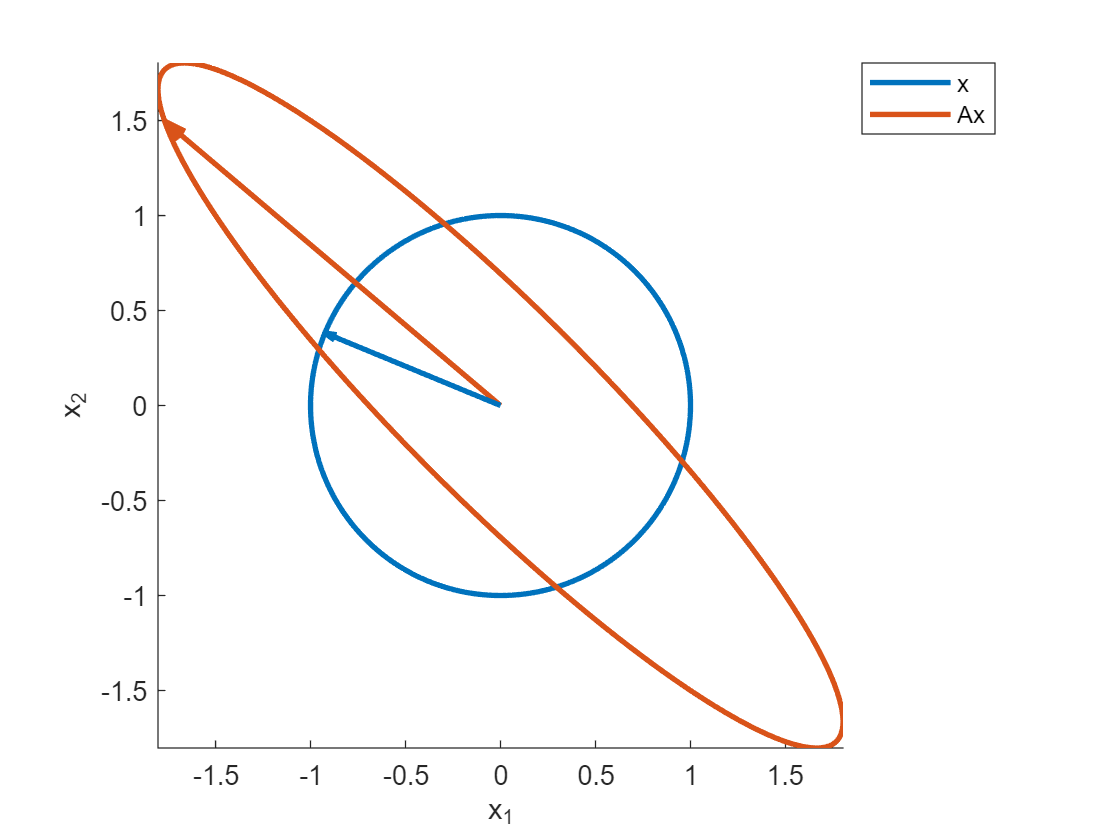

animate_matrix(A, [], [-0.92,0.38])

Indeed, the first singular vector of this matrix is $v_1$ = 

V(:,1)

Unrecognized function or variable 'V'.

Under multiplication by $A$, $v_1$ maps to $\sigma_1 u_1$, so the semi-major axis is along the direction $u_1$, and its length is $\sigma_1$:

Sigma(1,1), U(:,1)  % compare with the figure above

These are consistent with what we observe in the figure: the red vector looks about 2.7(ish) times the length of the blue and the direction looks right.

You could repeat the same check for the second set of singular vectors and singular value, which describe the semi-minor axis.

It's also informative to study the SVD equation in vector form.


$$AV = U\Sigma$$



$$A[v_1 | v_2 | \ldots | v_n] = [u_1 | u_2 | \cdots | u_n] \left[\matrix{\sigma_1 & 0 & \cdots & 0 \cr 0 & \sigma_2 & \ddots & \vdots \cr \vdots & \ddots & \ddots & 0 \cr 0 & \cdots & 0 & \sigma_n}\right]$$



$$Av_1 = \sigma_1 u_1 \\
Av_2 = \sigma_2 u_2 \\
\qquad \vdots\\
Av_n = \sigma_n u_n\\$$


We see that $A$ maps each of the *right singular vectors* $v_j$ onto $\sigma_j$ times the corresponding *left singular vector* $u_j$.

Notice the difference here between eigenvectors and singular vectors:

Eigenvectors:  $A w_j = \lambda_j w_j$   (same eigenvector $w_j$ on both sides)

Singular vectors:  $A v_j = \sigma_j u_j$  (right singular vector $v_j$ on the left, left singular vector $u_j$ on the right).

The terminology of singular vectors seems very odd all of a sudden.  When we write $A = U\Sigma\,V^T$ we have "left" ($u_j$) and "right" ($v_j$) singular vectors in their named positions.  But write $AV = U\Sigma$ and suddenly it's the $v_j$ on the left and the $u_j$ on the right.  It surely would have been better to use $AV = U\Sigma$ as the equation to decide which vectors were named "left" and "right", but instead we just have another example of clumsy mathematical terminology that we're stuck with.

Here's our animation for $A$, this time focusing on the singular vectors rather than eigenvectors (of which it has none!):

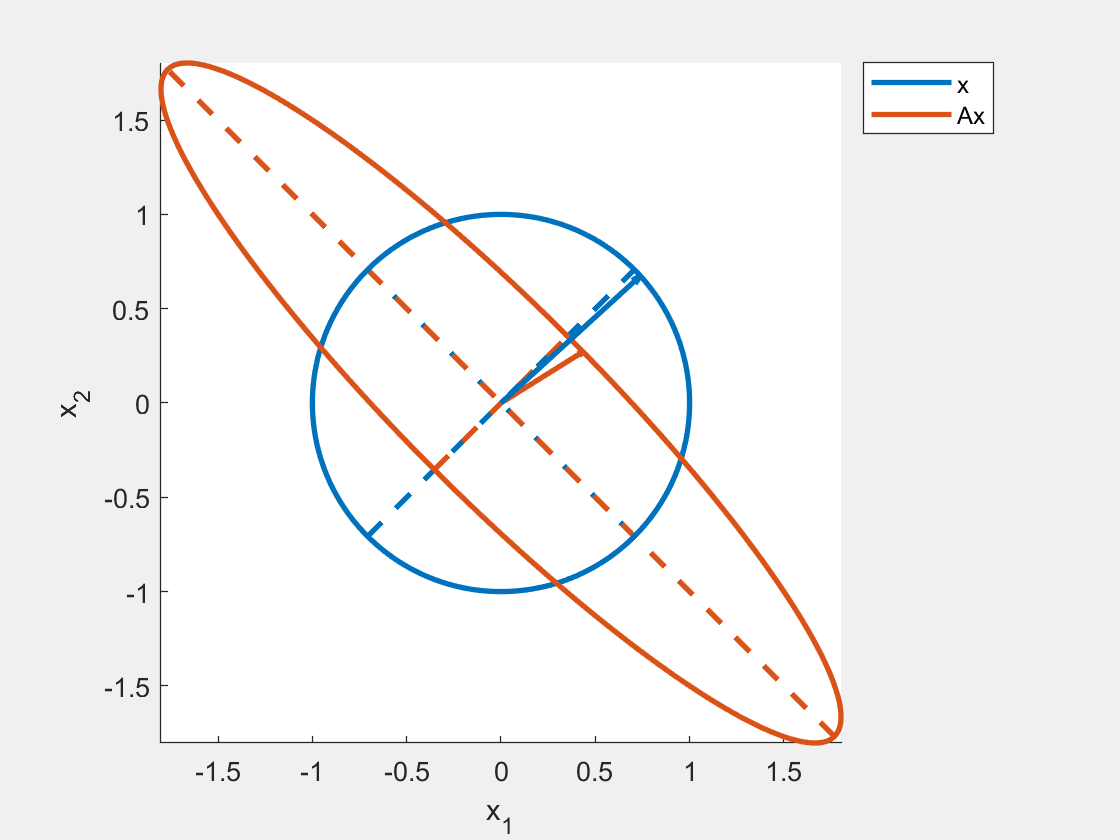

animate_matrix(A, 's')  % animation #2

The right singular vectors $v_1$ and $v_2$ are orthogonal, located along the dotted blue lines.  The left singular vectors $u_1$ and $u_2$ are orthogonal, located along the dotted red lines.

As already stated, the scaled left singular vectors $\sigma_j u_j$ correspond to the semi-major and semi-minor axes of the ellipse.  The right singular vectors $v_j$ are the unit vectors that $A$ maps on to these.

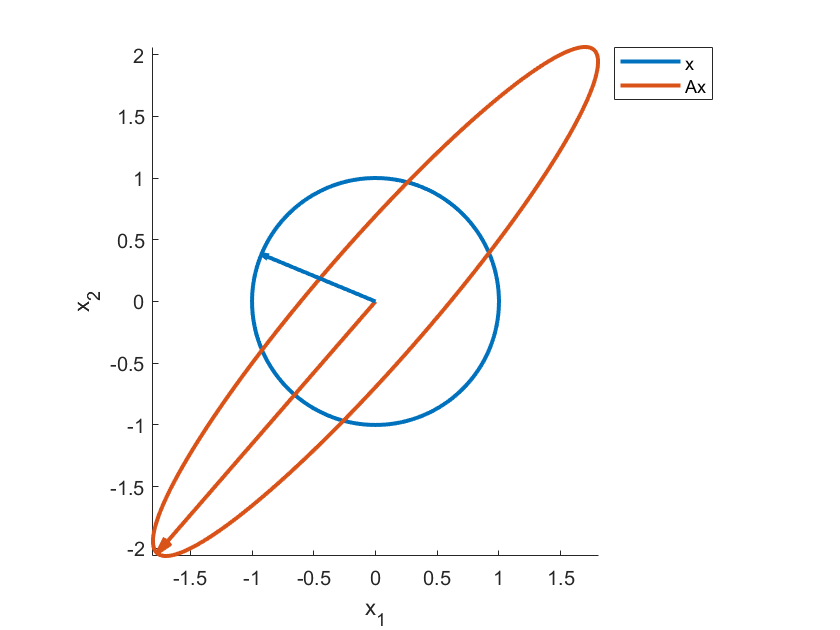

animate_matrix(A, '[]', V(:,1))  % semi-major axis

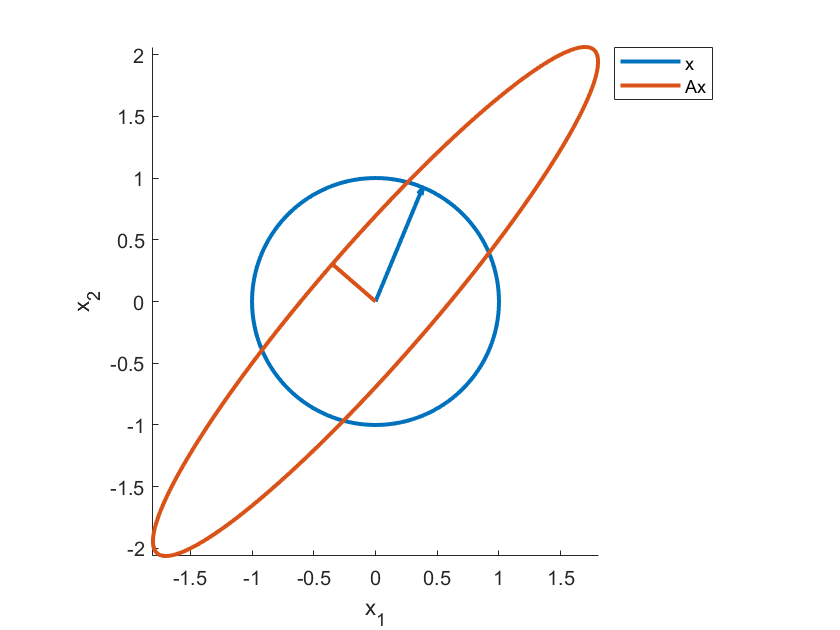

animate_matrix(A, '[]', V(:,2))  % semi-minor axis

[Video](https://web.microsoftstream.com/video/4caa8295-6957-4f03-8dce-6d6a762b4818)

Summary of SVD $A = U\Sigma V^T$ for square matrix $A \in \mathbb{R}^{n \times n}$.

- $\Sigma$ is an $n \times n$ diagonal matrix.  Its diagonal entries, $\sigma_j$ are the *singular values *of $A$.

- The singular values $\sigma_j$ are non-negative.

- The singular values $\sigma_j$ are the square roots of the eigenvalues of $A^TA$ (or $AA^T$).

- $U$ is an $n \times n$ orthogonal matrix.  Its columns are the *left singular vectors *of $A$.

- $V$ is an $n \times n$ orthogonal matrix.  Its columns are the *right singular vectors *of $A$.

## 5.3 Rectangular matrices

[Video](https://web.microsoftstream.com/video/0b58be18-aba2-40e7-bfaa-881456e9353c)

Now it's time to really amaze with the power of the SVD.  There is *nothing* stopping us from defining the SVD of a general $m \times n$ *rectangular* matrix.  We again aim for the decomposition $A = U\Sigma V^T$, with $U$ and $V$ orthogonal matrices, but now we need to think carefully about the dimensions.  $A \in \mathbb{R}^{m \times n}$ is rectangular.  $U$ and $V$ will still be square (so they can be orthogonal matrices), but to produce the right dimensions we need $U \in \mathbb{R}^{m \times m}$ and $V \in \mathbb{R}^{n \times n}$.  That leaves $\Sigma \in \mathbb{R}^{m \times n}$, no longer square, but rectangular like $A$.

The decomposition $A = U\Sigma V^T$ then implies

$A^TA = (U\Sigma V^T)^T (U\Sigma V^T) = V \Sigma^T U^T U \Sigma V^T = V \Sigma^T \Sigma V^T$   (i)

and

$AA^T = (U\Sigma V^T)(U\Sigma V^T)^T = U \Sigma V^T V \Sigma^T U^T = U \Sigma \Sigma^T U^T$  (ii)

with the only change to Section 5.2 that we have matrices $\Sigma^T \Sigma$ and $\Sigma \Sigma^T$ instead of $\Sigma^2$.  In fact, this is just what we want: $\Sigma$ still only has nonzero entries on its diagonal, and the matrices $\Sigma^T \Sigma$ and $\Sigma \Sigma^T$ are $n \times n$ and $m \times m$ respectively as required for (i) and (ii), with zeros padding out the remaining entries.

[Video](https://web.microsoftstream.com/video/2ff7c54f-1581-4d26-a20e-163699276883)

Let's now study a larger example to illustrate the four fundamental subspaces as in the video.

A = [
     3     5     4     6     3
     2     2    -5    -5     7
     2     0    -5    -7     3
    -6    -8    -6    -8    -4
     2     1     1     0    -1
    -6    -7    -6    -7    -2
     5     5    -1    -1     6]

A =      3     5     4     6     3
     2     2    -5    -5     7
     2     0    -5    -7     3
    -6    -8    -6    -8    -4
     2     1     1     0    -1
    -6    -7    -6    -7    -2
     5     5    -1    -1     6


 [U, Sigma, V] = svd(A)

U =    -0.4185    0.0092   -0.3681    0.8122    0.1481    0.0137    0.0864
    0.0733    0.6679   -0.4035   -0.0538   -0.2034   -0.2029   -0.5481
    0.2061    0.5194    0.4535    0.1777    0.6686    0.0099    0.0574
    0.6354   -0.0683    0.0695    0.4011   -0.3078   -0.5309    0.2220
   -0.0667   -0.0017    0.5958    0.3584   -0.4443    0.3403   -0.4459
    0.5690    0.0059   -0.3590    0.1083    0.0188    0.7292    0.0600
   -0.2124    0.5286    0.0854   -0.0689   -0.4441    0.1707    0.6612


Sigma =    23.0704         0         0         0         0
         0   15.1234         0         0         0
         0         0    3.6109         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000
         0         0         0         0         0
         0         0         0         0         0


V =    -0.3952    0.3581    0.6511   -0.4355   -0.3194
   -0.5262    0.2994    0.0918    0.7834    0.1059
   -0.4400   -0.4004    0.1451   -0.2605    0.7464
   -0.5710   -0.4591   -0.4141   -0.0875   -0.5329
   -0.2172    0.6411   -0.6125   -0.3480    0.2135


It's informative think of this decomposition in vector form.  Since $A \in \mathbb{R}^{m \times n}$ with $m > n$ ($A$ is a "tall" matrix), there are only $n$ right singular vectors (in $V$), but $m$ left singular vectors (in $U$).  We will use the notation $U_{1:n}$ and $U_{n+1:m}$ to denote the first $n$ columns of $U$ and the remaining columns of $U$ respectively (i.e. what we would call in MATLAB `U(:, 1:n)` and `U(:, n+1:m)`).  Blocking the right hand side of $AV = U\Sigma$ in this way, we have:


$$AV= [U_{1:n} | U_{n+1:m}]  \left[\matrix{\sigma_1 & 0 & \cdots & 0 \cr 0 & \sigma_2 & \ddots & \vdots \cr \vdots & \ddots & \ddots & 0 \cr 0 & \cdots & 0 & \sigma_n \cr \hline 0 & 0 & \cdots & 0 \cr \vdots & \vdots & \ddots & \vdots \cr 0 & 0 & \cdots & 0}\right ]$$



$$AV = U_{1:n} \times \textrm{diag}(\sigma_j) + U_{n+1:m} \times \textrm{diag}(0)$$



$$AV = U_{1:n} \times \textrm{diag}(\sigma_j)$$


So the extra columns in $U$ go unused; the extra rows of zeros in the $\Sigma$ matrix ensure this.  Looking just at $AV = U_{1:n} \times \textrm{diag}(\sigma_j)$, we have


$$A[v_1 | v_2 | \ldots | v_n] = [u_1 | u_2 | \cdots | u_n] \left[\matrix{\sigma_1 & 0 & \cdots & 0 \cr 0 & \sigma_2 & \ddots & \vdots \cr \vdots & \ddots & \ddots & 0 \cr 0 & \cdots & 0 & \sigma_n}\right ]$$


or, as separate equations for each singular vector:


$$Av_1 = \sigma_1 u_1 \\
Av_2 = \sigma_2 u_2 \\
\qquad \vdots\\
Av_n = \sigma_n u_n\\$$


Now let's look closely at our example, particularly the matrix $\Sigma$:

Sigma

Sigma =    23.0704         0         0         0         0
         0   15.1234         0         0         0
         0         0    3.6109         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000
         0         0         0         0         0
         0         0         0         0         0


The first three right singular vectors $v_1$, $v_2$, $v_3$ satisfy $Av_1 = \sigma_1 u_1$, $Av_2 = \sigma_2 u_2$, $Av_3 = \sigma_3 u_3$, where $\sigma_1 = 23.07$, $\sigma_2 = 15.12$ and $\sigma_3 = 3.61$.  So far, so good.

But we see that $\sigma_4 = 0$ and $\sigma_5 = 0$.  What does this mean?  It means $Av_4 = 0$ and $Av_5 = 0$.  Thus we see that $A$ has a nontrivial null space, spanned by $\{v_4, v_5\}$.  Indeed, $\{v_4, v_5\}$ is an orthonormal basis for the null space of $A$.

The first three right singular vectors $\{v_1, v_2, v_3\}$, being orthogonal to$\{v_4, v_5\}$, therefore form an orthonormal basis for the row space of $A$.

The number of nonzero singular values evidently determines the *rank* of the matrix: $\textrm{rank}(A) = \textrm{number of nonzero singular values}$.  The convention is to order the singular values in $\Sigma$ from largest to smallest, as shown here, so if $\sigma_{r+1}$ is the first singular value equal to zero, we have that $\textrm{rank}(A) = r$.  In this example, $r = 3$.

From $Av_1 = \sigma_1 u_1$, $Av_2 = \sigma_2 u_2$, $Av_3 = \sigma_3 u_3$ we know that the vectors $\{u_1, u_2, u_3\}$ are all in the column space of $A$.  Since the column space has dimension 3, same as the row space, $\{u_1, u_2, u_3\}$ form an orthonormal basis for the column space of $A$.

The remaining left singular vectors $\{u_4, u_5, u_6\}$ therefore form an orthonormal basis for the left null space of $A$.

The SVD really reveals an extraordinary amount of information about a matrix.  Here we summarise what we have learned.  This list now supersedes the one given in Section 5.2 (which is still true of course, but this list is more general and more detailed):

Summary of SVD $A = U\Sigma V^T$ for rectangular matrix $A \in \mathbb{R}^{m \times n}$.

- $\Sigma$ is an $m \times n$ diagonal matrix.  Its diagonal entries, $\sigma_j$ are the *singular values *of $A$.

-     The singular values $\sigma_j$ are non-negative.

-     The first $r$ singular values $\sigma_j$ are positive, where $r = \textrm{rank}(A)$.

-     The first $r$ singular values $\sigma_j$ are the square roots of the nonzero eigenvalues of $A^TA$ (or $AA^T$).

- $U$ is an $n \times n$ orthogonal matrix.  Its columns are the *left singular vectors *of $A$.

-     The first $r$ columns of $U$ are an orthonormal basis for the **column space** of $A$.

-     The last $m - r$ columns of $U$ are an orthonormal basis for the **left null space** of $A$.

- $V$ is an $n \times n$ orthogonal matrix.  Its columns are the *right singular vectors *of $A$.

-     The first $r$ columns of $V$ are an orthonormal basis for the **row space** of $A$.

-     The last $n - r$ columns of $V$ are an orthonormal basis for the **null space** of $A$.

[Video](https://web.microsoftstream.com/video/d50c89d7-d3d7-4f50-b4bf-6d0d7dcac547)

Remarkably, the SVD shows that *any linear transformation** from *$\mathbb{R}^n$* to *$\mathbb{R}^m$* can be represented by a diagonal matrix*, provided you choose the right bases for the domain and range spaces.  Compare:

Using the standard bases for $\mathbb{R}^n$ and $\mathbb{R}^m$:  We have a vector $x$, which we multiply by a matrix $A$ to get $b$.  $Ax = b$.

Using $A$'s SVD bases:  We represent $x$ by $x = Vc$ for some coordinate vector $c$.  And we represent $b$ by $b = Uk$ for some coordinate vector $k$.  Then


$$Ax = b$$



$$AVc = Uk$$



$$U^{-1}AVc = k$$



$$\Sigma c = k$$


*With respect to the SVD bases, a linear transformation from *$\mathbb{R}^n$* to *$\mathbb{R}^m$* is represented by a diagonal matrix.*

**Exercise**

On a piece of paper, go through this same process of showing how the SVD can represent an arbitrary linear transformation by a diagonal matrix.  Don't refer to back to the example video or lecture notes unless you really get stuck.▫

## 5.4 Reduced SVD

[Video](https://web.microsoftstream.com/video/a7b5e228-927d-45ca-b1de-ec7221f01a00)

Consider again the SVD of our most recent matrix $A$.

U, Sigma, V

U =    -0.4185    0.0092   -0.3681    0.8122    0.1481    0.0137    0.0864
    0.0733    0.6679   -0.4035   -0.0538   -0.2034   -0.2029   -0.5481
    0.2061    0.5194    0.4535    0.1777    0.6686    0.0099    0.0574
    0.6354   -0.0683    0.0695    0.4011   -0.3078   -0.5309    0.2220
   -0.0667   -0.0017    0.5958    0.3584   -0.4443    0.3403   -0.4459
    0.5690    0.0059   -0.3590    0.1083    0.0188    0.7292    0.0600
   -0.2124    0.5286    0.0854   -0.0689   -0.4441    0.1707    0.6612


Sigma =    23.0704         0         0         0         0
         0   15.1234         0         0         0
         0         0    3.6109         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000
         0         0         0         0         0
         0         0         0         0         0


V =    -0.3952    0.3581    0.6511   -0.4355   -0.3194
   -0.5262    0.2994    0.0918    0.7834    0.1059
   -0.4400   -0.4004    0.1451   -0.2605    0.7464
   -0.5710   -0.4591   -0.4141   -0.0875   -0.5329
   -0.2172    0.6411   -0.6125   -0.3480    0.2135


We showed earlier that we could drop the extra columns of $U$ and the rows of zeros at the bottom of $\Sigma$ to product a reduced decomposition

$A[v_1 | v_2 | \ldots | v_n] = [u_1 | u_2 | \cdots | u_n] \left[\matrix{\sigma_1 & 0 & \cdots & 0 \cr 0 & \sigma_2 & \ddots & \vdots \cr \vdots & \ddots & \ddots & 0 \cr 0 & \cdots & 0 & \sigma_n}\right ]$.

Here is that decomposition now:

v = V, sigma = Sigma(1:5, 1:5), u = U(:, 1:5)

v =    -0.3952    0.3581    0.6511   -0.4355   -0.3194
   -0.5262    0.2994    0.0918    0.7834    0.1059
   -0.4400   -0.4004    0.1451   -0.2605    0.7464
   -0.5710   -0.4591   -0.4141   -0.0875   -0.5329
   -0.2172    0.6411   -0.6125   -0.3480    0.2135


sigma =    23.0704         0         0         0         0
         0   15.1234         0         0         0
         0         0    3.6109         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000


u =    -0.4185    0.0092   -0.3681    0.8122    0.1481
    0.0733    0.6679   -0.4035   -0.0538   -0.2034
    0.2061    0.5194    0.4535    0.1777    0.6686
    0.6354   -0.0683    0.0695    0.4011   -0.3078
   -0.0667   -0.0017    0.5958    0.3584   -0.4443
    0.5690    0.0059   -0.3590    0.1083    0.0188
   -0.2124    0.5286    0.0854   -0.0689   -0.4441


Notice that $\Sigma$ becomes square, and $U$ becomes rectangular in this "reduced" SVD.  Still, unless you really need the extra columns of $U$ (because you really do want a basis for the left null space) you might as well just use the reduced SVD.  MATLAB calls it the "economy-sized" decomposition, which you request as follows:

[U,Sigma,V] = svd(A, 'econ')

U =    -0.4185    0.0092   -0.3681    0.8122    0.1481    0.0137    0.0864
    0.0733    0.6679   -0.4035   -0.0538   -0.2034   -0.2029   -0.5481
    0.2061    0.5194    0.4535    0.1777    0.6686    0.0099    0.0574
    0.6354   -0.0683    0.0695    0.4011   -0.3078   -0.5309    0.2220
   -0.0667   -0.0017    0.5958    0.3584   -0.4443    0.3403   -0.4459
    0.5690    0.0059   -0.3590    0.1083    0.0188    0.7292    0.0600
   -0.2124    0.5286    0.0854   -0.0689   -0.4441    0.1707    0.6612


Sigma =    23.0704         0         0         0         0
         0   15.1234         0         0         0
         0         0    3.6109         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000
         0         0         0         0         0
         0         0         0         0         0


V =    -0.3952    0.3581    0.6511   -0.4355   -0.3194
   -0.5262    0.2994    0.0918    0.7834    0.1059
   -0.4400   -0.4004    0.1451   -0.2605    0.7464
   -0.5710   -0.4591   -0.4141   -0.0875   -0.5329
   -0.2172    0.6411   -0.6125   -0.3480    0.2135


Now only the utilised columns of $U$ are returned, but it's no longer an orthogonal matrix (because it's no longer square).  It still satisfies $U^TU = I$ of course.  And the decomposition $A = U \Sigma V^T$ certainly still holds.

norm(A - U*Sigma*V')  % as good as zero

ans = 1.7447e-14

## 5.5 Pseudoinverse

[Video](https://web.microsoftstream.com/video/ba9f9324-aec6-411e-96ee-b270ca789d44)

One of the many uses of the SVD is to solve the "ultimate" generalisation of $Ax = b$.  Here we state this generalisation as two steps:

- Solve the least squares problem $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$.  There may be infinitely many solutions $x$ to this problem.

- Of all the solutions $x$ from part 1, choose the solution with minimum norm $\|x\|$.

This problem always has a unique solution, which can be obtained as follows.

- The least squares problem may be formulated by projecting $b$ onto the column space.  The system $Ax = \textrm{Proj}_{\textrm{colspace}(A)}(b)$ is consistent, but may have infinitely many solutions.

- The unique solution of minimum norm to part 1 is the projection of the general solution $x_\textrm{general}$ onto the row space: $x = \textrm{Proj}_{\textrm{rowspace}(A)}(x_\textrm{general})$.

We introduce the notation $A^+$ for the *pseudoinverse *of $A$, such that the solution to the generalised problem 1-2 is $x = A^+ b$.

The SVD provides a convenient way to calculate the pseudoinverse.  Simply put, if $A = U\Sigma V^T$, then $A^+ = V\Sigma^+U^T$.  Here $\Sigma^+$ is the pseudoinverse of $\Sigma$, which is just the transpose of $\Sigma$ except that all nonzero singular values $\sigma_i$ are replaced by their reciprocals $1/\sigma_i$.

*Let the SVD of *$A \in \mathbb{R}^{m \times n}$* be *$A = U\Sigma V^T$*.  Then the pseudoinverse of *$A$ is $A^+ = V\Sigma^+U^T$*.*

*The pseudoinverse *$\Sigma^+$* of the diagonal matrix *$\Sigma$* is found by reciprocating its nonzero entries and transposing.*

How does this recipe using the SVD calculate the pseudoinverse?  The answer is in the mapping that the SVD establishes from the row space basis to the column space basis: $v_j \rightarrow \sigma_j u_j$ for $j = 1,\ldots r$.  This mapping inverts to $u_j \rightarrow v_j / \sigma_j$ .  Neither of the null spaces are involved in problem 1-2 at all!  Step 1 projects $b$ onto the column space, thereby throwing away any left null space component it may have had.  And step 2 projects the solution $x_\textrm{general}$ onto the row space, thereby throwing away any null space component it may have had.  Hence, the essence of this "pseudo-inversion" is simply reciprocating the nonzero singular values: $\sigma_j$ becomes $1/\sigma_j$.

Geometrically, the pseudoinverse is the unique linear transformation that maps vectors in the column space onto their preimage in the row space, and maps vectors in the left null space to zero.

MATLAB has the command `pinv` to compute the pseudoinverse.  We won't spend any time performing such calculations ourselves by picking apart the SVD, but if you're curious, you can just `type pinv` to see that's exactly what MATLAB is doing in the `pinv `command.

Aplus = pinv(A)  % calculate pseudoinverse of A

Aplus =    -0.0590   -0.0582    0.0905    0.0000    0.1085   -0.0743    0.0316
    0.0004    0.0013    0.0171   -0.0141    0.0166   -0.0220    0.0175
   -0.0071   -0.0353    0.0005   -0.0075    0.0253   -0.0254   -0.0065
    0.0523    0.0242   -0.0729   -0.0216   -0.0666    0.0269   -0.0206
    0.0668    0.0961   -0.0569   -0.0207   -0.1005    0.0558    0.0099


We can put this pseudoinverse to work for us.  Suppose we want to find the minimum norm solution to $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$.  That is, of all the solutions $x$ to this least squares problem, we want the one which minimises $\|x\|$.  That's exactly what the pseudoinverse computes for us.  The solution is simply $x = A^+ b$.

b = (1:7)'  % make up some right hand side

b =      1
     2
     3
     4
     5
     6
     7


x = Aplus * b

x =     0.4140
    0.0716
   -0.1779
   -0.5203
   -0.0928


First of all, this solution $x$ minimises $\|b - Ax\|$; that is, it solves the least squares problem.

norm(b - A*x)  % this is a small as it could be

ans = 8.7147

One way to check this is to verify that $x$ satisfies the normal equations $A^TAx = A^Tb$.

norm(A'*b - A'*A*x)  % numerically zero

ans = 7.4183e-14

But this matrix $A$ is not of full rank, so there are infinitely many least squares solutions.  Among all of them, the $x$ we found has the minimum norm.

norm(x)  % this is also as small as it could be!

ans = 0.6982

One way to check this is to verify that $x$ has no component in the null space of $A$.

norm(null(A)' * x)  % numerically zero

ans = 1.8041e-16

So the pseudoinverse is the ultimate one-stop-shop for solving least squares problems, including those with infinitely many solutions.  But it's really just a convenient packaging for applying the theory of the SVD.  It's the SVD that has identified the inverse mapping from column space back to row space, which unlocks the whole problem.

## 5.6 Truncated SVD and low-rank approximation

[Video](https://web.microsoftstream.com/video/e5e3bd1a-83ee-4c79-9ba8-299a9da2c9e1)

Consider now the reduced SVD $A = U\Sigma V^T$ written out in vector form:


$$A = [u_1 | u_2 | \cdots | u_n] \left[\matrix{\sigma_1 & 0 & \cdots & 0 \cr 0 & \sigma_2 & \ddots & \vdots \cr \vdots & \ddots & \ddots & 0 \cr 0 & \cdots & 0 & \sigma_n}\right ] \left[\matrix{v_1^T \cr v_2^T \cr \vdots \cr v_n^T}\right]$$


If we expand the right hand side, we see that $A$ can be written as the sum of rank-1 matrices:


$$A = \sum_{j=1}^n \sigma_j\, u_j\, {v_j}^T$$


If $A$ has rank $r$, and hence only $r$ nonzero singular values, we can truncate the sum at $j = r$, to get


$$A = \sum_{j=1}^r \sigma_j \, u_j \, {v_j}^T$$


But remember, the singular values $\sigma_j$ are ordered from largest to smallest.  So, if we wished to *approximate* $A$ by a matrix of lower rank, we could even truncate the sum at $j = \nu$, for some $\nu < r$, to generate a rank-$\nu$ approximation to $A$:


$$\tilde{A} = \sum_{j=1}^\nu \sigma_j \, u_j \, {v_j}^T$$


It can be shown in fact, that $\tilde{A}$ is the "nearest" matrix of rank $\nu$ to $A$.

How is this helpful?  Well, consider a matrix of large dimension, but with many of its singular values quite small.  In many applications we can settle for an approximation of $A$ that is formed through consideration of only the first $\nu$ largest singular values, and leaving off the contribution of the many smaller ones.  It requires only the storage of the 2$\nu$ singular vectors $u_j$ and $v_j$ for $j = 1\ldots \nu$ (either can be scaled by $\sigma_j$) to represent $\tilde{A}$.  If $\nu \ll n$ this might be a considerable saving.

Here we will take an example of image compression.  We load a greyscale image of a waterfall.

I = imread('waterfall.jpg');
I = double(I) / 255;  % convert from uint8 to double
size(I)

ans =         2688        1920


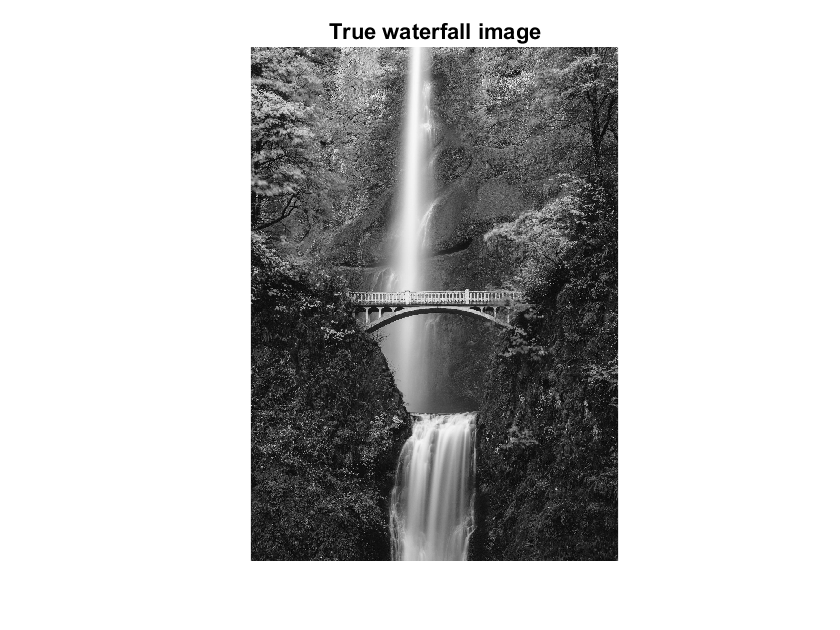

figure
imshow(I, 'initialmagnification', 'fit')
title('True waterfall image')

In memory, the matrix `I` has 2688 rows and 1920 columns, with rank 1920.  But it can very likely be closely approximated by a matix of much lower rank.  Let's take the reduced SVD and inspect the singular values.

[U,Sigma,V] = svd(I, 'econ')  % Reduced SVD: U has the same size as A; Sigma and V are square

U =    -0.0269   -0.0130    0.0320    0.0230    0.0325    0.0315   -0.0111   -0.0081    0.0033    0.0454    0.0219   -0.0059   -0.0005    0.0122    0.0020    0.0009   -0.0471    0.0161    0.0009   -0.0140    0.0680    0.0046   -0.0129   -0.0116   -0.0158   -0.0319    0.0124    0.0002   -0.0158   -0.0148   -0.0127    0.0193   -0.0452    0.0170    0.0068   -0.0455   -0.0170    0.0587    0.0219   -0.0152    0.0021    0.0462   -0.0098   -0.0149    0.0239    0.0481   -0.0085   -0.0134   -0.0036    0.0227
   -0.0272   -0.0125    0.0317    0.0244    0.0360    0.0264   -0.0070   -0.0069    0.0037    0.0409    0.0152   -0.0141    0.0009    0.0080    0.0087    0.0027   -0.0459    0.0133    0.0068   -0.0205    0.0774    0.0062   -0.0129   -0.0096   -0.0098   -0.0430    0.0207    0.0051   -0.0112   -0.0118   -0.0203    0.0173   -0.0527    0.0186    0.0004   -0.0415   -0.0200    0.0531    0.0154   -0.0134    0.0075    0.0413   -0.0124   -0.0066    0.0204    0.0634   -0.0059   -0.0016   -0.0121    0

Sigma =   796.5537         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  168.6854         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

V =    -0.0154   -0.0161    0.0181   -0.0032    0.0042    0.0216   -0.0380    0.0300   -0.0261    0.0165   -0.0369    0.0240   -0.0324    0.0045   -0.0102    0.0395   -0.0345    0.0377   -0.0121    0.0062   -0.0013    0.0147   -0.0674    0.0065   -0.0507    0.0071   -0.0057    0.0064   -0.0151    0.0409   -0.0031   -0.0365    0.0013    0.0360   -0.0351    0.0058    0.0057   -0.0342    0.0542   -0.0355   -0.0124   -0.0147   -0.0320   -0.0356    0.0093   -0.0235    0.0021   -0.0599    0.0218   -0.0213
   -0.0153   -0.0159    0.0174   -0.0027    0.0027    0.0240   -0.0443    0.0338   -0.0244    0.0164   -0.0336    0.0232   -0.0354    0.0001   -0.0155    0.0312   -0.0348    0.0410   -0.0122   -0.0005   -0.0064    0.0097   -0.0735    0.0067   -0.0481    0.0093   -0.0027    0.0192   -0.0115    0.0365   -0.0025   -0.0356    0.0114    0.0266   -0.0294    0.0001    0.0054   -0.0454    0.0518   -0.0310   -0.0175   -0.0173   -0.0354   -0.0265    0.0036   -0.0229    0.0032   -0.0764    0.0280   -0

Let's look at how the singular values $\sigma_j$ decay with increasing $j$.

sigma = diag(Sigma)

sigma =   796.5537
  168.6854
  122.2854
   86.5283
   54.6379
   49.6637
   47.7438
   44.4724
   43.1282
   40.9747


Better yet, let's plot $\sigma_j / \sigma_1$ against $j$, so we see the relative decay in magnitude.

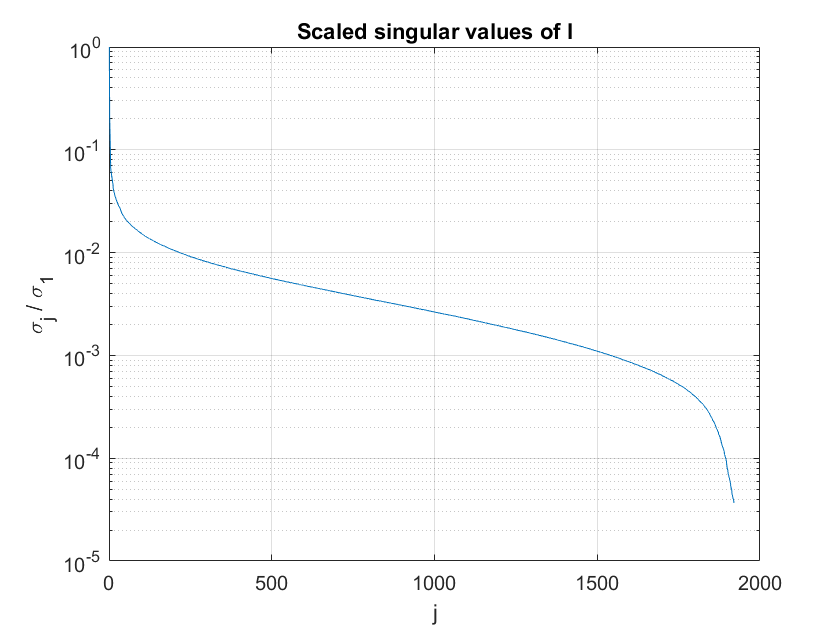

figure
semilogy(sigma / sigma(1))
grid on
xlabel('j')
ylabel('\sigma_j / \sigma_1')
title('Scaled singular values of I')

From this graph, it appears the sum $A_\nu = \sum_{j=1}^\nu \sigma_j \, u_j \, {v_j}^T$ of only around $\nu = 100$ terms would give good "value for money", with nearly two orders of magnitude of information content in $I$ captured.

Let's look at how the reconstructed image evolves with increasing values of $\nu$, up to $\nu = 100$.

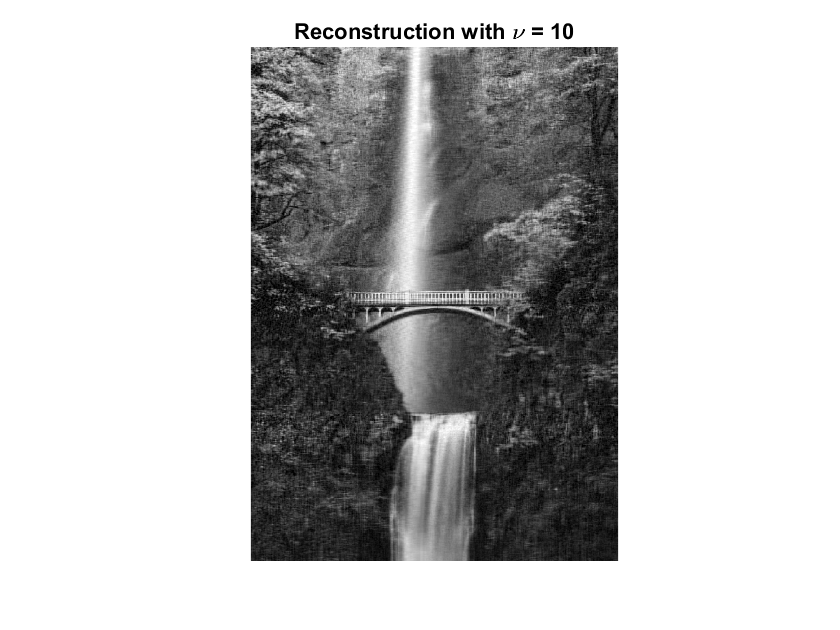

nu =10;
handle = imshow(A, 'initialmagnification', 'fit');
A = sigma(1:nu)' .* U(:,1:nu) * V(:,1:nu)';
title(sprintf('Reconstruction with \\nu = %d', nu)),

While it's not perfect, it's pretty decent.  Storing this image using the first 100 left and right singular vectors would require just over 3.5 MB (check it!), compared to nearly 40 MB for the full uncompressed image.

To be clear, this *isn't* how image compression is done in the real world.  There are better ways than this, which take advantage of how human visual perception works.  But it's a fun little example to illustrate how large matrices that come from "real data" (in this case, pixel values of an image) can often be closely approximated by matrices of much lower rank.

### Principal Component Analysis

[Video](https://web.microsoftstream.com/video/54a08e06-4f95-41c0-bf23-95f5c5f795a2)

As more and more decisions in the real world are being driven by analysing large data sets, the importance of low-rank approximation is becoming more important with each passing year.  Statisticians use SVD to determine the "principal components" of a data set -- this is called Principal Component Analysis (PCA).  Machine learning practitioners use SVD to identify the most relevant "features" of a data set, which might then be used to train an algorithm to recommend movies to users based on their viewing histories for example.  In these applications, $A$ is not an image, but rather a collection of columns (representing the explanatory variables in a statistical model, say).  It is usually more convenient in these applications to think of the trunctated SVD $A_\nu = \sum_{j=1}^\nu \sigma_j \, u_j \, {v_j}^T$ in terms of how it reconstructs individual columns of $\tilde{A}$:

$\tilde{A}$`(:,j)` $= U$`(:, 1:`$\nu$`) `$\Sigma$`(1:`$\nu$`, 1:`$\nu$`) `$V$`(j, 1:`$\nu$`)`$^T$   (MATLAB-style notation)

If we define the vector $x_j =$ $\Sigma$`(1:`$\nu$`, 1:`$\nu$`) `$V$`(j, 1:`$\nu$`)`$^T$ then we have

$\tilde{A}$`(:,j)` $= U$`(:, 1:`$\nu$`)`  $x_j$

The vector $x_j \in \mathbb{R}^{\nu \times 1}$ is the coordinate vector of the column $\tilde{A}$`(:,j),` in terms of the basis of left singular vectors $U$`(:, 1:`$\nu$`)`.  To put it another way, $x_j$ is the coordinate vector of the projection of $A$`(:,j)` onto this $\nu$-dimensional space of singular vectors.

To be clear, the truncated SVD is doing the same thing either way you look at it.  It's just a question of what is the most useful interpretation for a given application: approximating $A$ by a sum of relatively few rank-1 matrices, or approximating columns of $A$ by their projections onto a relatively low-dimensional space.

## **5.7 Summary**

- The singular value decomposition (SVD) $A = U\Sigma V^T$ is defined for all rectangular matrices $A \in \mathbb{R}^{m \times n}$.

- The **full SVD **returns orthogonal matrices $U \in \mathbb{R}^{m \times m}$ and $V \in \mathbb{R}^{n \times n}$ and nonnegative diagonal matrix $\Sigma \in \mathbb{R}^{m \times n}$.

- The sorted diagonal entries of $\Sigma$, $\sigma_j$ are the *singular values *of $A$.  If $\sigma_{r} \neq 0$ and $\sigma_{r+1} = 0$ then $A$ has rank $r$.

- The columns of $U$ are called *left singular vectors*, and the columns of $V$ are called *right singular vectors.*

- The left and right singular vectors provide orthonormal bases for all four fundamental subspaces of $A$.

- The pseudoinverse of $A$ is $A^+ = V\Sigma^+U^T$.

- The **reduced SVD** is commonly used when $A \in \mathbb{R}^{m \times n}$ has more rows than columns.

-     The reduced SVD is still $A = U\Sigma V^T$ but now $U \in \mathbb{R}^{m \times n}$ (rectangular), and $\Sigma \in \mathbb{R}^{n \times n}$, $V \in \mathbb{R}^{n \times n}$ (both square).

- The **truncated SVD** uses only the first $\nu$ columns of $U$ and $V$.

-     As a sum of rank-1 matrices, this takes the form $\tilde{A} = \sum_{j=1}^\nu \sigma_j \, u_j \, {v_j}^T$, which is the best rank-$\nu$ approximation of $A$.

-     In terms of the columns of $\tilde{A}$, it takes the form $\tilde{A}$`(:,j)` $= U$`(:, 1:`$\nu$`) `$\Sigma$`(1:`$\nu$`, 1:`$\nu$`) `$V$`(j, 1:`$\nu$`)`$^T$ $= U$`(:, 1:`$\nu$`)`  $x_j$